# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves firm's investment problem.

%}

## Model: Model of Firm Investment.

The representative firm is infinitely lived. It maximizes the present value of its lifetime profit by choosing capital investment subject to a convex cost of adjustment. The dynamic programming problem associated with this is:


$$V(A,K,p) = \underset{i}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{i}{K}\right)^2K - pi + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ ,$$



$$K' = (1-\delta)K + i  \ , $$


where $p$ is the price of investment, $|\rho|<1$ and $\epsilon'\sim\mathcal{N}(0,\sigma^2)$. Substituting the law of motion gives


$$V(A,K,p) = \underset{K'}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{K' - (1-\delta)K}{K}\right)^2K - p(K' - (1-\delta)K) + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ .$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 2'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 2 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously..

% Load and separate firm parameters
par = model.setup();     % Setup parameters and read data

    id2015     l1       group     capital_mil    total_cost    avg_revenue      profit   
    ______    _____    _______    ___________    __________    ___________    ___________

    10697       180    "big"             NaN      5.949e+05      6.11e+05           16100
    10698       140    "big"            2500          48000         80000           32000
    10700        50    "big"             200            NaN         40000             NaN
    10702       110    "big"            8000          48400         47000           -1400
    10705        60    "big"             NaN           8500         15000            6500
    10721        72    "big"             NaN     1.0757e+05     1.996e+05           92032
    10724       311    "big"           10

par = model.gen_grids(par); % Generate grids, now par has kgrid, Agrid, etc.

    0.5378    0.4391    0.0231    0.0000    0.0000    0.0000         0
    0.0644    0.5835    0.3407    0.0113    0.0000    0.0000    0.0000
    0.0009    0.1078    0.6382    0.2480    0.0052    0.0000    0.0000
    0.0000    0.0022    0.1691    0.6575    0.1691    0.0022    0.0000
    0.0000    0.0000    0.0052    0.2480    0.6382    0.1078    0.0009
    0.0000    0.0000    0.0000    0.0113    0.3407    0.5835    0.0644
    0.0000    0.0000    0.0000    0.0000    0.0231    0.4391    0.5378

    0.5378    0.4391    0.0231    0.0000    0.0000    0.0000         0
    0.0644    0.5835    0.3407    0.0113    0.0000    0.0000    0.0000
    0.0009    0.1078    0.6382    0.2480    0.0052    0.0000    0.0000
    0.0000    0.0022    0.1691    0.6575    0.1691    0.0022    0.0000
    0.0000    0.0000    0.0052    0.2480    0.6382    0.1078    0.0009
    0.0000    0.0000    0.0000    0.0113    0.3407    0.5835    0.0644
    0.0000    0.0000    0.0000    0.0000    0.0231    0.4391    0.5378




par_big = par.bigf;      % Extract the bigf table for analysis or further steps
par_small = par.smallf;  % Same for smallf

## Solve the model using Value Function iteration.

Calls: solve.m and model.m.

We will solve the model using value function iteration. Our guess is that firm value is zero over the state space.


$$V(A,K) = 0 \ .$$


% Create a new struct with both:
par_big_struct = par;          % Copy all parameters (including grids)
par_big_struct.data = par_big; 

% Now call solve using this new struct
t = cputime;
sol_big = solve.firm_problem(par_big_struct);

Solving for firm group: big
------------Beginning Value Function Iteration.------------
Iteration 1, diff = 24.95788491
Iteration 2, diff = 18.62436394
Iteration 3, diff = 12.24573099
Iteration 4, diff = 7.40523554
Iteration 5, diff = 4.31785909
Iteration 6, diff = 2.52894689
Iteration 7, diff = 1.53886960
Iteration 8, diff = 1.03107232
Iteration 9, diff = 0.72291460
Iteration 10, diff = 0.53207871
Iteration 11, diff = 0.41007110
Iteration 12, diff = 0.33010574
Iteration 13, diff = 0.27472120
Iteration 14, diff = 0.23543208
Iteration 15, diff = 0.20652635
Iteration 16, diff = 0.18439182
Iteration 17, diff = 0.16696993
Iteration 18, diff = 0.15287050
Iteration 19, diff = 0.14113708
Iteration 20, diff = 0.13117977
Iteration 21, diff = 0.12258297
Iteration 22, diff = 0.11504404
Iteration 23, diff = 0.10835105
Iteration 24, diff = 0.10234717
Iteration 25, diff = 0.09691335
Iteration 26, diff = 0.09195792
Iteration 27, diff = 0.08740816
Iteration 28, diff = 0.08320638
Iteration 29, diff = 0

elapsed_time = cputime - t;
disp(['Elapsed CPU time: ', num2str(elapsed_time)]);

Elapsed CPU time: 1348.2031


% Create a new struct with both:
par_small_struct = par;          % Copy all parameters (including grids)
par_small_struct.data = par_small; % Add your big table as a separate field

% Now call solve using this new struct
t = cputime;
sol_small = solve.firm_problem(par_small_struct);

Solving for firm group: small
------------Beginning Value Function Iteration.------------
Iteration 1, diff = 24.95788491
Iteration 2, diff = 18.62436394
Iteration 3, diff = 12.24573099
Iteration 4, diff = 7.40523554
Iteration 5, diff = 4.31785909
Iteration 6, diff = 2.52894689
Iteration 7, diff = 1.53886960
Iteration 8, diff = 1.03107232
Iteration 9, diff = 0.72291460
Iteration 10, diff = 0.53207871
Iteration 11, diff = 0.41007110
Iteration 12, diff = 0.33010574
Iteration 13, diff = 0.27472120
Iteration 14, diff = 0.23543208
Iteration 15, diff = 0.20652635
Iteration 16, diff = 0.18439182
Iteration 17, diff = 0.16696993
Iteration 18, diff = 0.15287050
Iteration 19, diff = 0.14113708
Iteration 20, diff = 0.13117977
Iteration 21, diff = 0.12258297
Iteration 22, diff = 0.11504404
Iteration 23, diff = 0.10835105
Iteration 24, diff = 0.10234717
Iteration 25, diff = 0.09691335
Iteration 26, diff = 0.09195792
Iteration 27, diff = 0.08740816
Iteration 28, diff = 0.08320638
Iteration 29, diff =

elapsed_time = cputime - t;
disp(['Elapsed CPU time: ', num2str(elapsed_time)]);

Elapsed CPU time: 1332.1094


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a single firm over time.

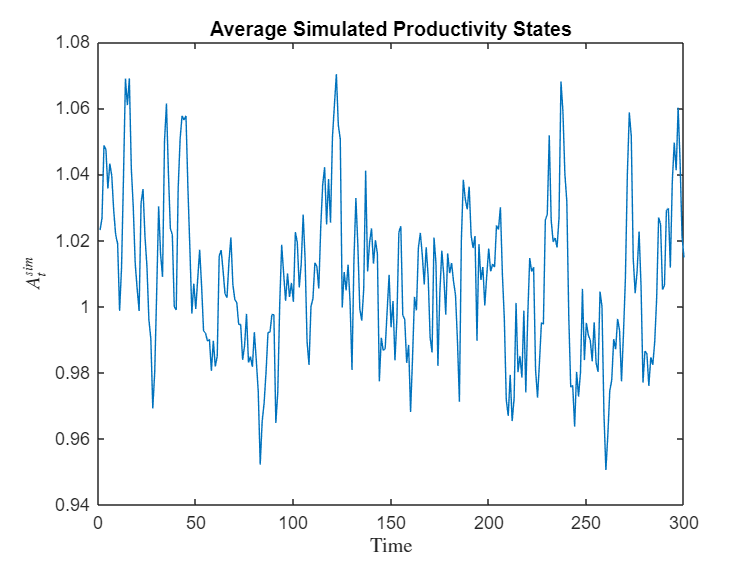

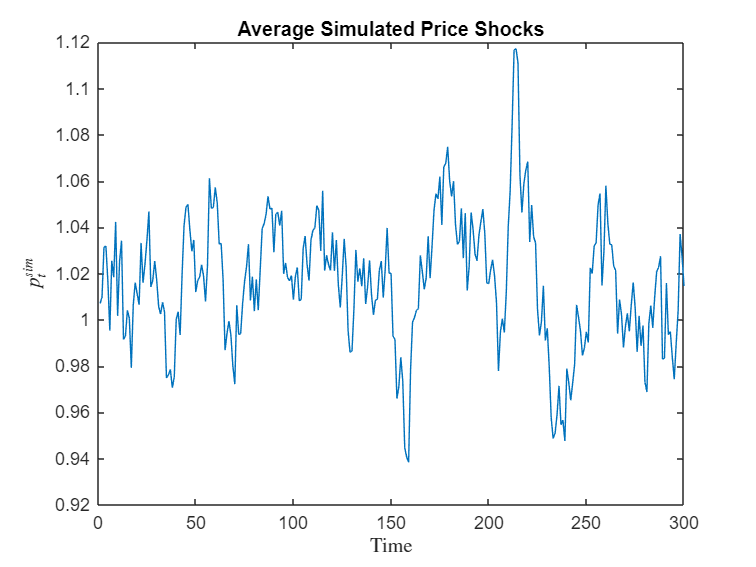

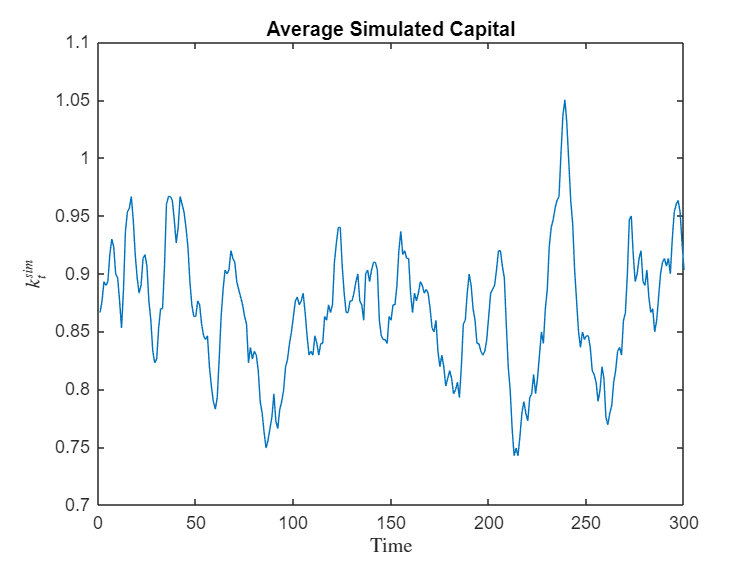

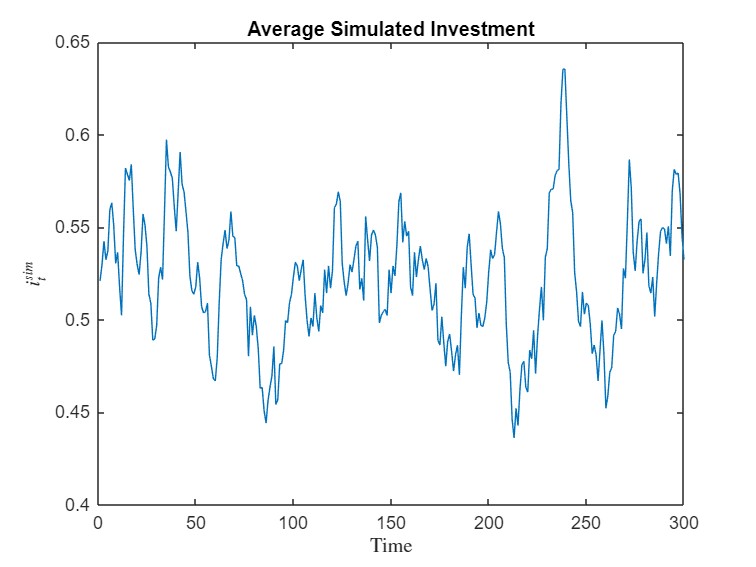

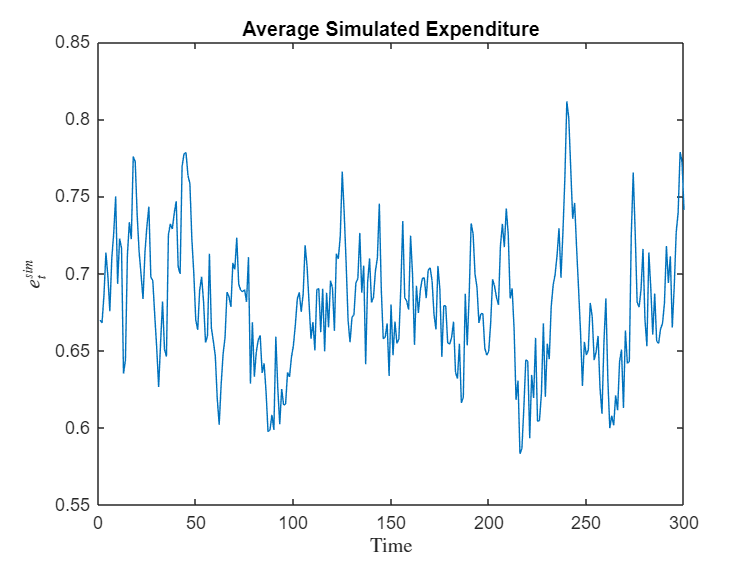

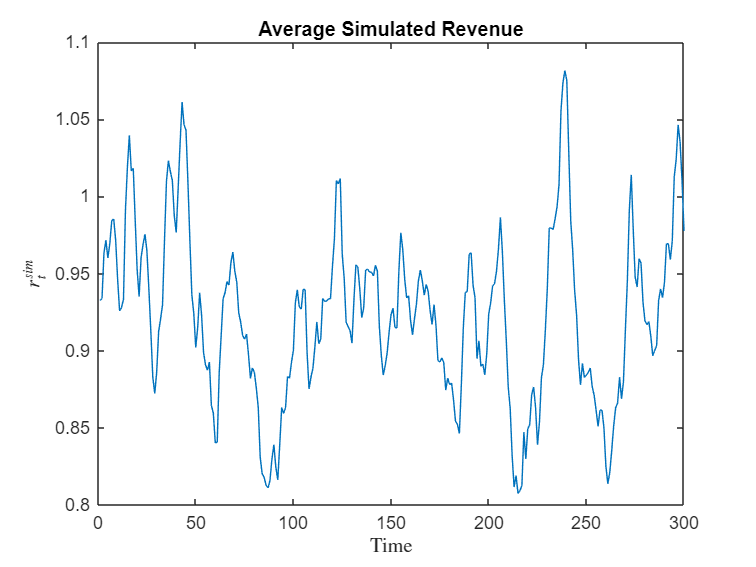

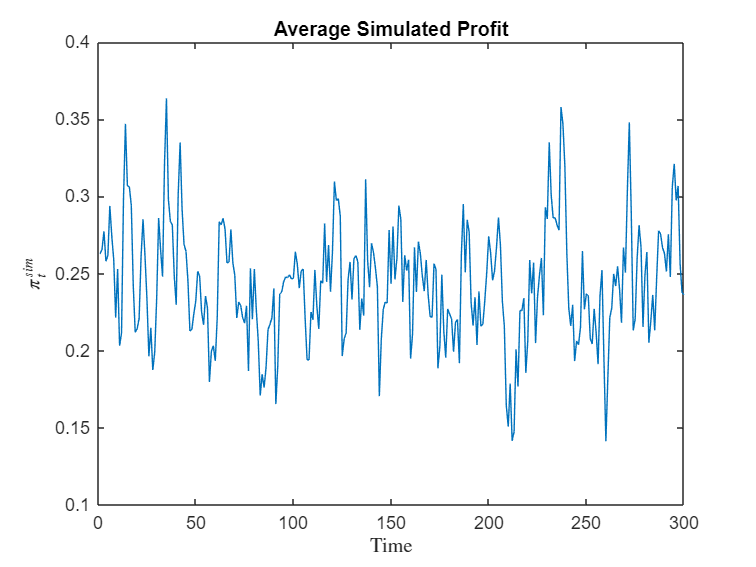

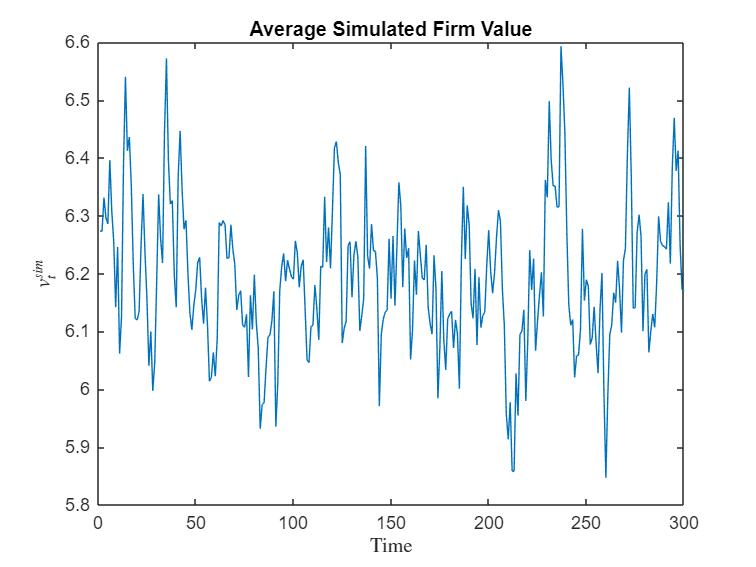

sim_big = simulate.firm_dynamics(par_big_struct,sol_big); % Simulate the model.
my_graph.plot_policy(par_big_struct,sol_big,sim_big) % Plot the model functions and time series.

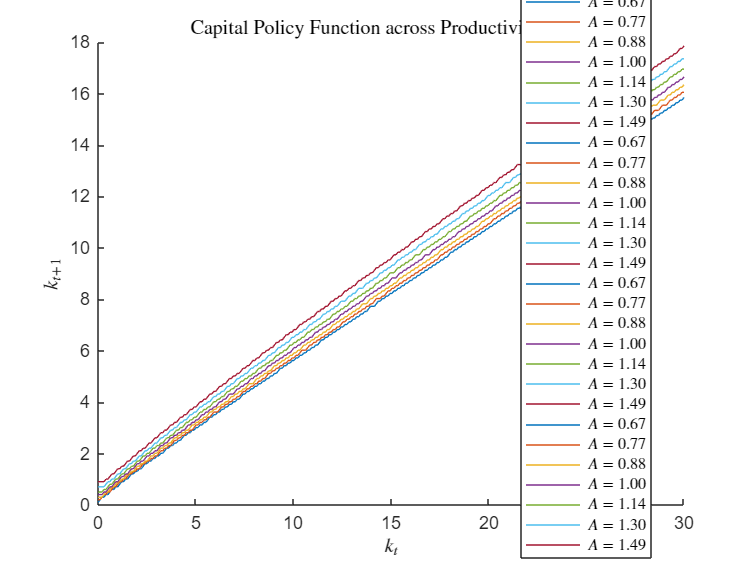

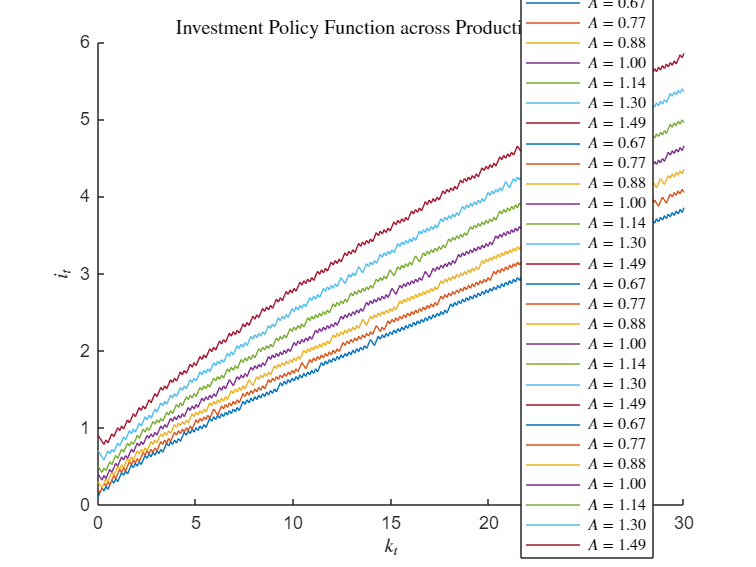

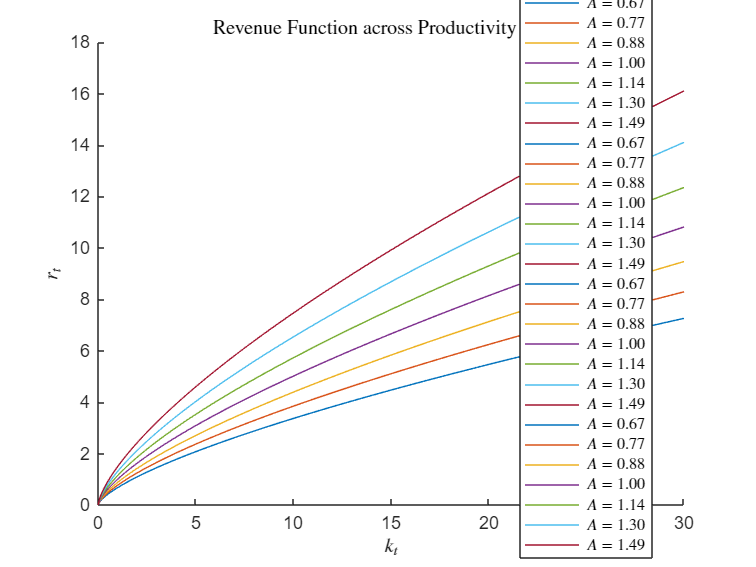

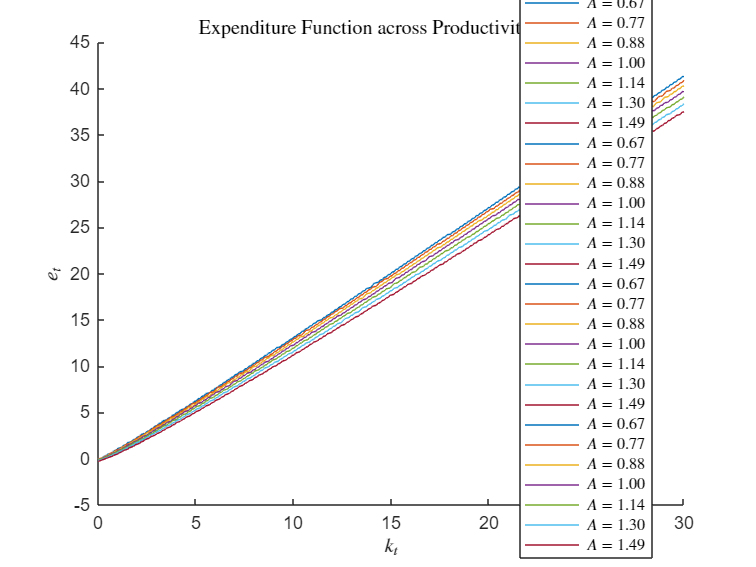

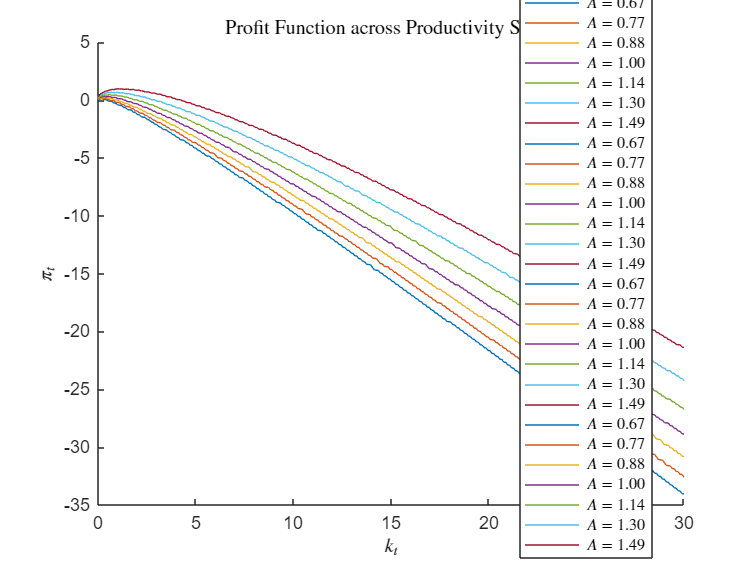

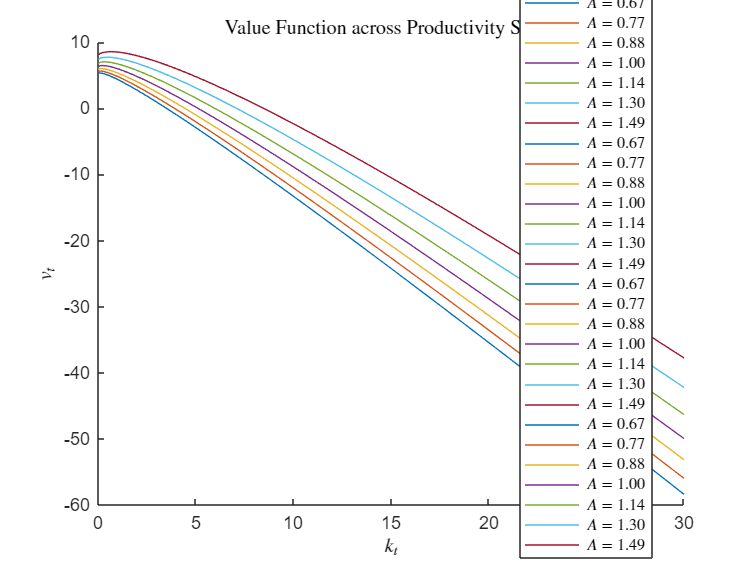

sim_small = simulate.firm_dynamics(par_small_struct,sol_small); % Simulate the model.
my_graph.plot_policy(par_small_struct,sol_small,sim_small) % Plot the model functions and time series.